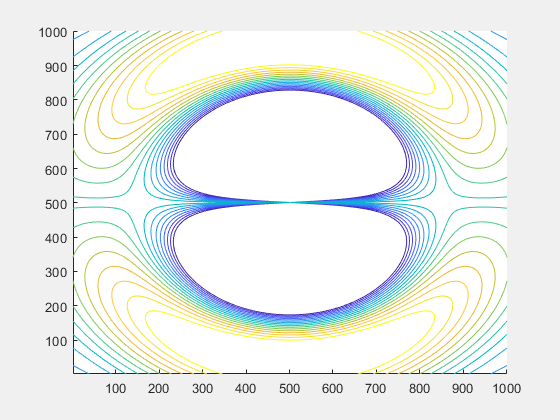

clear
clc
epsilon= 8.85e-12;%fre space permitivity
f = 3e9;%frequency
c = 3e8;%speed of light
w = 2*pi*f;%omega
lambda = c/f;%wavelength
B = 2*pi/lambda; %beta
dl = lambda/500; %length of antenna
dt=1/f/20;
I0 = 1;%current
[x,z]=meshgrid(-lambda:dl:lambda,-lambda:dl:lambda);
r = (x.^2+z.^2).^(1/2);
theta = atan(x./z);
n = B/(w*epsilon);
E1 = n*I0*dl/(2*pi);
E2 = cos(theta);
E3 = r.^(-2)-r.^(-3)*1i/B;
E4 = exp(-1i*B*r);
E =E1*E2.*E3.*E4;%r component of the field
n= 100;
% M = moviein(n);
M(n) = struct('cdata',[],'colormap',[]);%Initializing Matrix to store frames
h = figure;
ax = gca;
ax.NextPlot = 'replaceChildren';
h.Visible = 'off';%Hiding figure for speed up 
v = -1:0.13:1;%parameter for scaling contour plots
for xx=1:n
    t=xx*dt;
    Et=real(E*exp(1j*w*t));%converting to time domain
    contour(Et,v)
    drawnow
    M(xx) = getframe;
end
h.Visible = 'on';

movie(M);shg